# EE 4540 Introduction to Machine Learning – Group assignment – Version2

Brian Martinez Josh Saunders

## Intialization

close all
clear all

data = dataLoad();
[NT,F]=size(data);              % number of rows and columns
Npatients=max(data(:,1));       % number of subjects
ntrain=36;

% Data preparation
%
[ Ntimes,w_prep, data_train_norm, data_test_norm ] = data_prep_norm( ntrain,Npatients,data );
%

## Regression

% Declare universal variables for base workspace
%
nbins=50;           % number of bins for histogram
eps_g=0.00001;      % stopping criterion for gradient algorithm
gamma_g=eps_g/10;   % step for gradient algorithm
eps_s=0.00001;      % stopping criterion for steepest descent algorithm
index=[5 7];
%

% Declare array to build struct with in loop
%
mmse =[];
pcr =[];
performance=[];
%

for ind=1:2

## MMSE

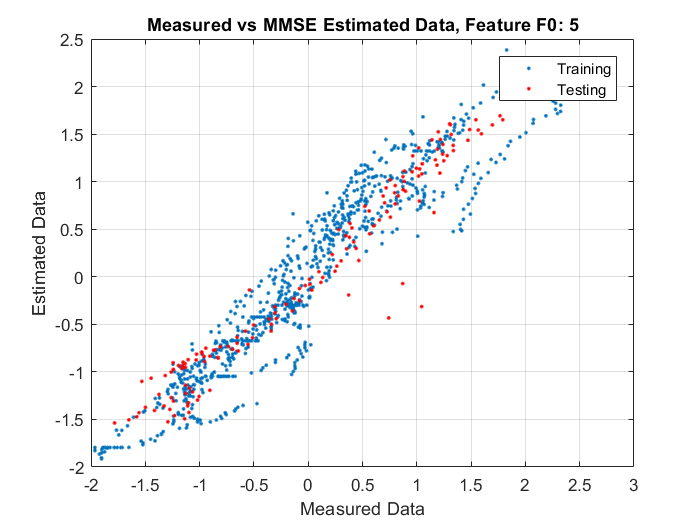

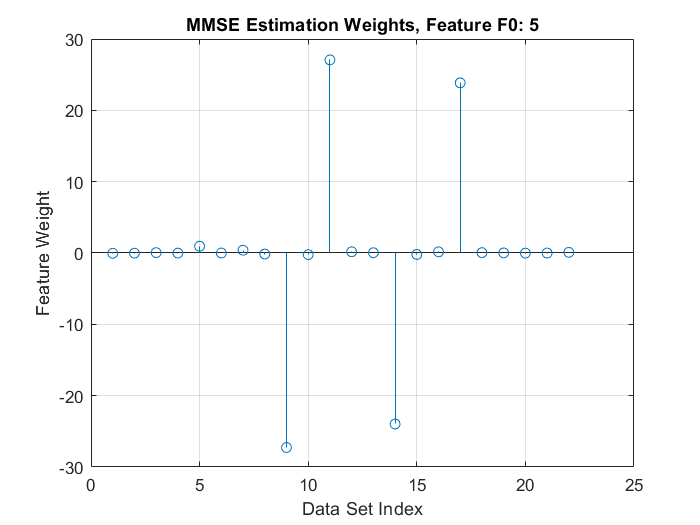

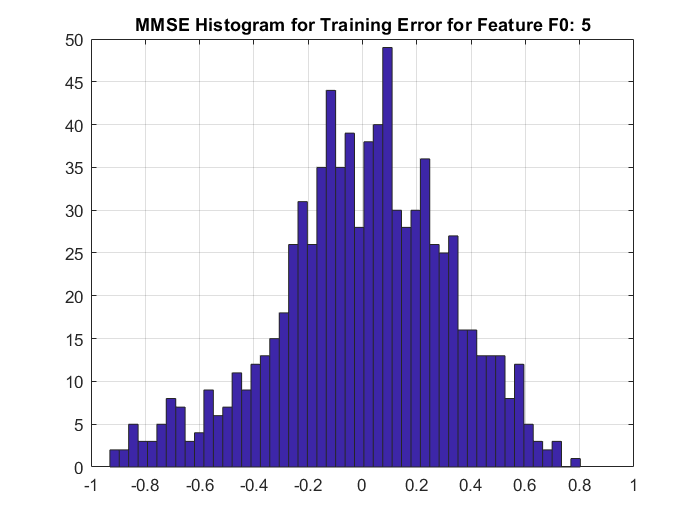

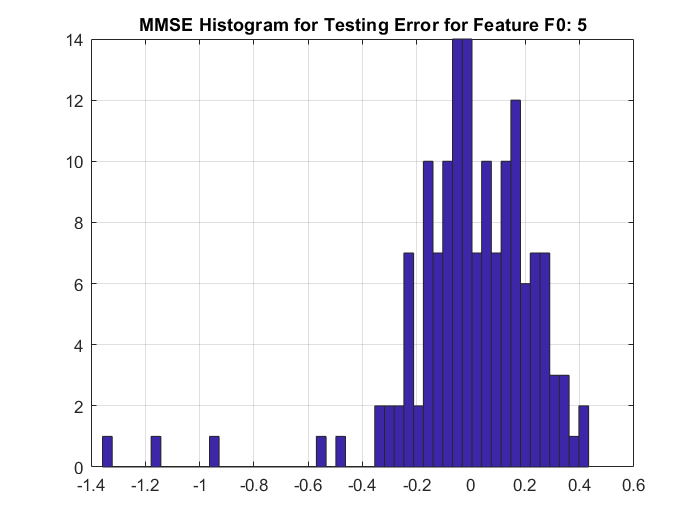

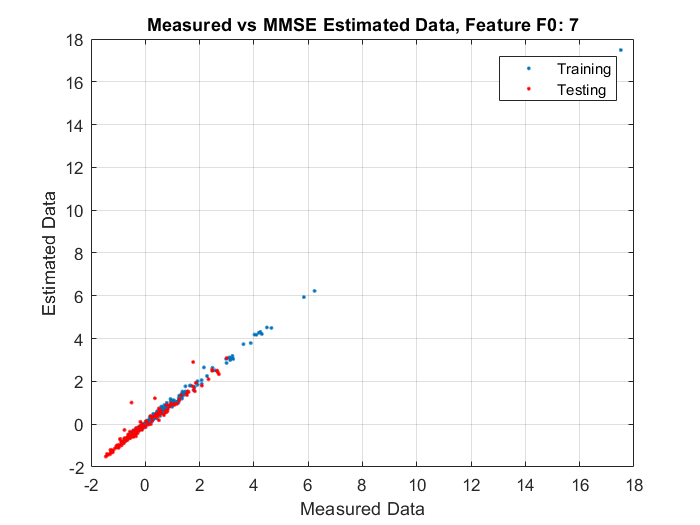

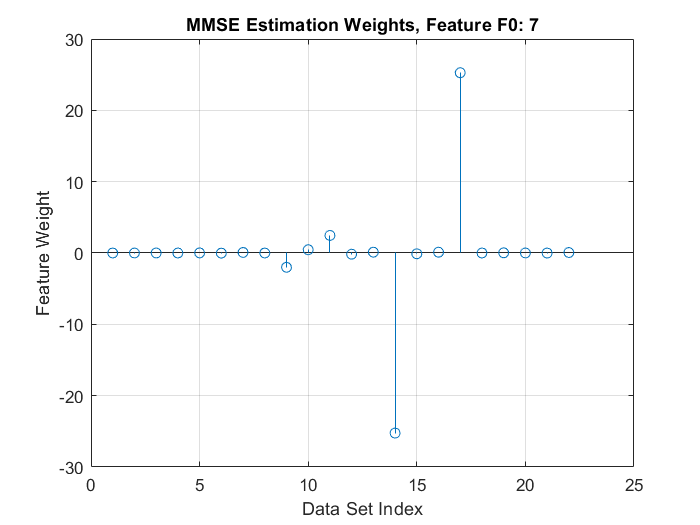

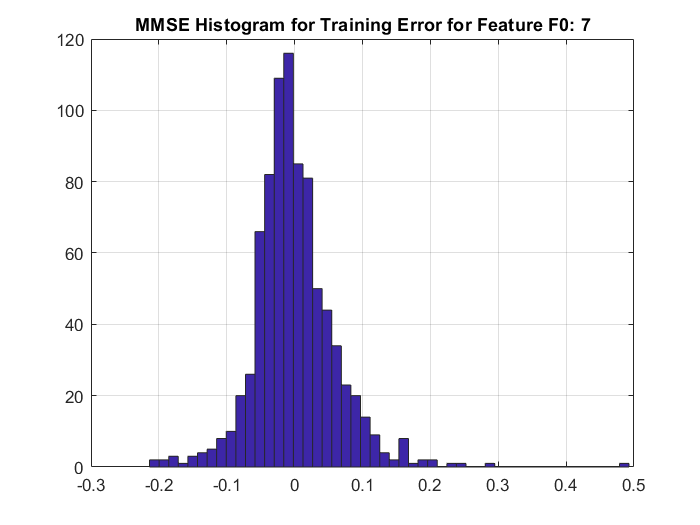

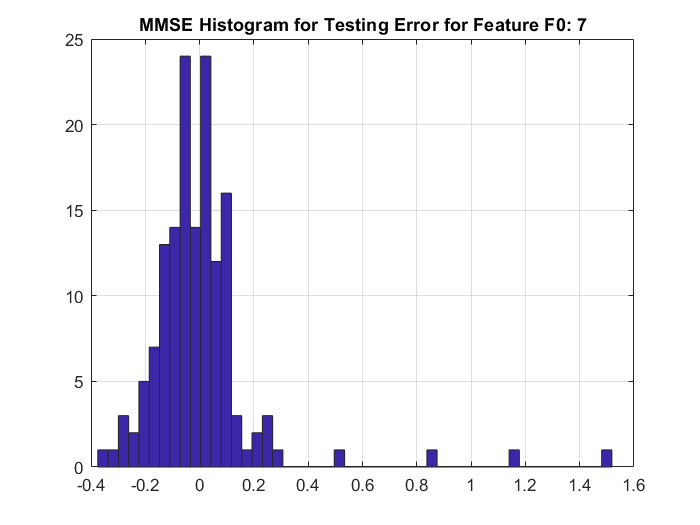

    F0=index(ind);
    [ mmse ] = mmseEST(F0,data_train_norm,data_test_norm,nbins, mmse );
    mlplot(mmse(ind));

    a_train_mmse(:,ind)=ones(21,1)*mmse(ind).acc.train;
    a_test_mmse(:,ind)=ones(21,1)*mmse(ind).acc.test;

## PCR

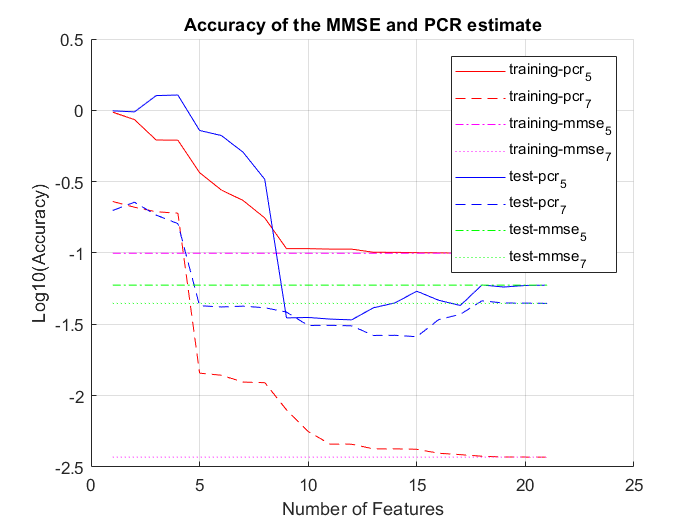

    for L=1:F-1
       [ pcr ] = pcrEST(F0,data_train_norm,data_test_norm,L,nbins,pcr);
       a_train_pcr(L,ind)=pcr((ind-1)*21+L).acc.train;
       a_test_pcr(L,ind)=pcr((ind-1)*21+L).acc.test;
    end
%     a_pcrT.train = a_train_pcr(ind);
%     a_pcrT.test = a_test_pcr(ind);
%         
%     a_pcr =[a_pcr a_pcrT];
%  
end
performance.type= 'p-log';
performance.accPCR.train = a_train_pcr;
performance.accPCR.test = a_test_pcr;
performance.accMMSE.train = a_train_mmse;
performance.accMMSE.test =a_test_mmse;


% Plot Estimation Accuracy 
mlplot(performance);

## Questions

Q1: Yes, the performance Figure 9 in figure clearly shows how the PCR out performs MMSE after redundant features have been removed. However, notice that the accuracy for F0=5 is greater than F0=7. This is because F0=7 has outliers shown in Figure 5. Perhaps accuracy is alone is not the best indicator of performance. 

Q2: We must remove 4 features for there to be amarked improvement 

Q3: This proved more difficult- after trial and error we found that 5 feature can be removed and still see some improvement.

Q4: Per Figure 9, F0=5 improves dramatically after 8 features remain; F0=7 shows similar improvement after 4 features remain. 

Q5: It is clear manual tuning works, but it works under very specific conditions. Perhaps better suited applications would be prediction of single target that builds on historical data. This implementation seeks to build a characteristic image of useful to identify a feature of choice from data. This would account for the less prominent improvement.